# Electrochemical Cell Modeling

Author: Aditya Koranne

Date: 3/20/2021

This code regenerates results from 'Electrochemistry Based Battery Modeling For Prognostics' by Matthew Daigle and Chinmay S Kulkarni.

Battery Voltage 'V' ( an algebraic equation) is given by,


$$V=V_{U,p} -V_{U,n} -{V_o }^{\prime } -{V_{\eta ,p} }^{\prime } -{V_{\eta ,n} }^{\prime }$$


Where, 


$$\begin{array}{l}
V_{U,i} =\textrm{Equilibrium}\;\textrm{Potential}\;\textrm{given}\;\textrm{by}\;\textrm{Nernst}\;\textrm{Equation}\;\textrm{affected}\;\textrm{by}\;\textrm{Concentration}\;\textrm{Overpotential}\;\textrm{and}\;\textrm{Redlich}-\textrm{Kister}\;\textrm{activity}\;\textrm{correction}\\
V_o =\textrm{Ohmic}\;\textrm{Potential}\;\textrm{including}\;\textrm{electrodes},\textrm{electrolyte}\;\textrm{and}\;\textrm{current}\;\textrm{collector}\\
V_{\eta ,i} =\textrm{Surface}\;\textrm{Overpotential}\;\textrm{given}\;\textrm{by}\;\textrm{Butler}-\textrm{Volmer}\;\textrm{Equation}\;\textrm{and}\;\textrm{caused}\;\textrm{due}\;\textrm{to}\;\textrm{charge}\;\textrm{transfer}\;\textrm{resistance}\;\textrm{and}\;\textrm{SEI}\;\textrm{kinetics}\;
\end{array}$$


By formula,


$$\begin{array}{l}
V_{U,i} =U_{0,i} +\frac{\textrm{RT}}{\textrm{nF}}\ln \frac{\left(1-x_{s,i} \right)}{x_{s,i} }+V_{\textrm{INT},i} \\
V_{\textrm{INT},i} =\frac{1}{\textrm{nF}}\left(\sum_{k=0}^{N_i } A_{i,k} \left({\left(2x_i -1\right)}^{\left(k+1\right)} -\frac{\left(2x_i k\left(1-x_i \right)\right)}{{\left(2x_i -1\right)}^{1-k} }\right)\right)\\
V_0 =i*R_0 \\
{V_0 }^{\prime } =\frac{\left(V_0 -{V_0 }^{\prime } \right)}{t_0 }\\
{V_{\eta ,i} }^{\prime } =\frac{\left(V_{\eta ,i} -{V_{\eta ,i} }^{\prime } \right)}{t_{\eta ,i} }
\end{array}$$


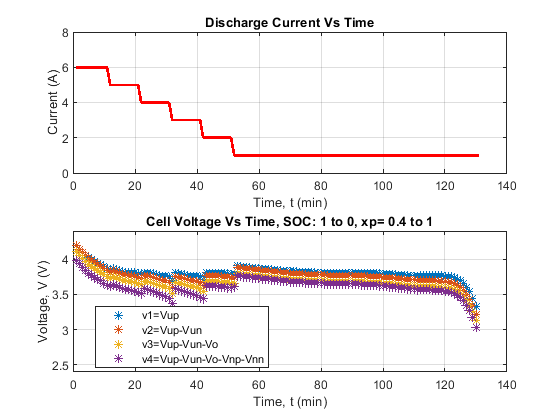

% Battery Parameters
clear all;
qmax=1.32E+04;
R=	8.314;
T=	292;
F=	96487;
n=	1;
D=	7.00E+06;
t0=	10;
alpha=	0.5;
R0=	0.085;
Sp=	2.00E-04;
kp=	2.00E+04;
vsp=	2.00E-06;
vbp=	2.00E-05;
tnp=	9.00E+01;
Sn=	2.00E-04;
kn=	2.00E+04;
vsn=	2.00E-06;
vbn=	2.00E-05;
tnn=	9.00E+01;

U0p=4.03;
Ap=[-33642.23;
    0.11;
    23506.89;
    -74679.26;
    14359.34;
    307849.79;
    85053.13;
    -1075148.06;
    2173.62;
    991586.68;
    283423.47;
    -163020.34;
    -470297.35;];
U0n=0.01;
An=[86.19];

% Calculate Voltages (Vup, Vun, Vo, Vnp, Vnn)
ii=1; xp=0.4;xn=1-xp;
for t=0:1*60:10000*60 % time in seconds
    qtransfer=i*t;
    xp=0.4+qtransfer/qmax;
    xn=1-xp;
    result=0;
    
    for k=1:13
        temp=Ap(k)*((2*xp-1)^(k-1+1)-((2*xp*(k-1)*(1-xp)/(2*xp-1)^(1-(k-1)))));
        result=result+temp;
    end
    
    VINTp=1/(n*F)*result;
    VINTn=1/(n*F)*An*((2*xn-1)^(1));
    
    Vup(ii)=U0p+(R*T)/(n*F)*log((1-xp)/xp)+VINTp; %#ok<*SAGROW> 
    Vun(ii)=U0n+(R*T)/(n*F)*log((1-xn)/xn)+VINTn; 

    % Discharge Current
    if (t<=10*60)
        i=6;
    elseif (t>10*60) && (t<=20*60)
        i=5;
    elseif (t>20*60) && (t<=30*60)
        i=4;
    elseif (t>30*60) && (t<=40*60)
        i=3;
    elseif (t>40*60)&&(t<=50*60)
        i=2;
    elseif t>50*60
        i=1;
    end
    current(ii)=i; %to plot current
    
    %Ohmic Overpotential (Depends on current only)
    Vo=i*R0;
    
    %Surface Overpotential (dependent on current and Mole Fraction (SOC))
    Jp=i/Sp;Jn=i/Sn;% Current density
    Jp0=kp*(1-xp)^alpha*(xp)^(1-alpha);% Exchange current density
    Jn0=kn*(1-xn)^alpha*(xn)^(1-alpha);
    
    Vnp(ii)=R*T/(F*alpha)*asinh(Jp/(2*Jp0));
    Vnn(ii)=R*T/(F*alpha)*asinh(Jn/(2*Jn0));
    
    if xp>=0.99
        break
    end
    ii=ii+1;
    
end
Vup(end)=[];Vun(end)=[];
Vnp(end)=[];Vnn(end)=[];

%Cell output voltage (V)
V=Vup-Vun-Vo-Vnp-Vnn;

%Make plots

subplot(2,1,1);
plot(current,'LineWidth',2,'Color','r');
title ('Discharge Current Vs Time');
ylabel('Current (A)');
xlabel('Time, t (min)');
ylim([0 8])
grid on

subplot(2,1,2);
v1=Vup;
plot(v1,'*'); hold on
v2=Vup-Vun;
plot(v2,'*');
v3=Vup-Vun-Vo;
plot(v3,'*');
v4=Vup-Vun-Vo-Vnp-Vnn;
plot(v4,'*');hold off

ylim([2.4 4.4]);
legend('v1=Vup','v2=Vup-Vun','v3=Vup-Vun-Vo','v4=Vup-Vun-Vo-Vnp-Vnn','Location',"best");
title('Cell Voltage Vs Time, SOC: 1 to 0, xp= 0.4 to 1')
ylabel('Voltage, V (V)')
xlabel('Time, t (min)')
grid on